# **Introduction to MATLAB Programming Language**

This is a MATLAB live notebook tutorial to introduce some MATLAB programming basics and modular programming concepts. Please click the **Run Section **button in the LIVE EDITOR toolstrip when you want to run the code in current section.

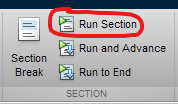

## Learning Objectives

***Introductory MATLAB Programming***

By the end of this notebook, students should be able to:

- Write basic functions

- Write small programs using MATLAB's control flow (for loop, while loop, if-else statement)

- Use array data structures to input and recall data.

- Make and format basic (line, surface) plots

- Recognize common error codes and how to fix them.

## Importance of Programming to... 

**The experimentalist**: You'll likely need to be able interpret experimental data you gather ([Minitab](http://www.minitab.com/en-us/case-studies/fresnillo-plc/), [JMP](https://www.jmp.com/en_us/customer-stories/kirin-beer.html)). It's also good to keep in mind that experimentalists benefit from having some modeling and programming tools at your disposal since you may need to automate laboratory equipment or design custom measurement devices. 

**The process engineer at a factory**: Modern industry loves continuous data collection... The typical process engineer must be able to interpret the data provided by instrumentation, perform analysis on this, and use computational tools to design experiments and implement quality control measures (again, using [Minitab](http://www.minitab.com/en-us/case-studies/fresnillo-plc/), [JMP](https://www.jmp.com/en_us/customer-stories/kirin-beer.html), other propriety software). 

**The controls engineer**: Simulation and testing of proposed control systems using MATLAB/Simulink has become such standard practice that several  major vendors such as [Rockwell Automation](about:blank<#null>) and [Ametek](https://www.ametek.com/pressreleases/news/2019/july/ametek-vis-new-intelligent-control-module-enhances) include built-in MATLAB/Simulink integration. 

**The modeling and simulation engineer**: May use [CFD](https://www.ansys.com/-/media/ansys/corporate/resourcelibrary/article/aa-v7-i2-cardiovascular-engineering.pdf) and multiphysics packages to design products, equipment, and improve processes. In fact, this specialization is highly dependent on this. While a number of important tasks require the use of specialized software, user-defined scripts often must be added to available multiphysics simulations.

**The data/quantitative scientist**: You'll end up leveraging machine learning tools like PyTorch, Tensorflow, R, and Python extensively. 

## MATLAB Basics

MATLAB® is a widely used programming language focused around matrix and array representation of data. It's desktop environment allow for iterative analysis of problems. it includes a large number of MATLAB toolboxes are professionally developed, rigorously tested, and fully documented. It includes the [Live Editor](https://www.mathworks.com/products/matlab/live-editor.html) for creating scripts that combine code, output, and formatted text in an executable notebook.

### MATLAB - Variables & Data Types

When programming, we often want to store a "piece" of information for later use. To do this we create a variable. You can think of a variable as some box which contains a piece of data. Once you've stored the data here, you can access and manipulate it by referring to the variable.

var_1 = 5
var_2 = "high five"
var_3 = var_1^2

In the above example, we made two different types of variables, a **double**-precision floating-point number, and a string. By default, MATLAB stores all numeric values as a double-precision floating point numbers.

### MATLAB - Arrays

An **array** is the basic structure for storing data.  A 1-D array is a vector and a 2-D array is a matrix.  You can have higher-dimensional arrays, although they tend to be encountered less frequently.  Some useful functions which construct arrays are included below. Take a minute to look over each constructor.

zeros(3)
zeros(4,4)
ones(3,1)
rand(2,3)

Let's now store a value to an array and then retrieve it.

a = rand(2)
a(1,2)
a(2,1) = 3

- `a(1,2)` retrieves the value stored at index `(1,2)` of `a;`

- `a(2,1) = 3` stores the value `3` at index `(2,1)` of `a;`

You can also make arrays using a bracket notation. A **Matrix** can be declared by using square brackets surrounding a list of row elements (values separated by commas or spaces) separated by semicolons.

a = [1; 2; 3; 4] % use ; within the array to go to next row (here we have a column vector) 
b = [1.1, 2.1, 2]% use , or space to specify next component in the same row (here we have a row vector)
c = [1.0 2.1; 3.1 5.1]% here we have a 2x2 array (matrix)

### MATLAB - Functions

A function is a basic programming construct that takes inputs, performs a series of operations, and then potentially returns an output. Functions are used because:

- They can be re-used and adapted readily. 

- It's much easier to check to see if small segments of code function properly than long programs. 

Note that in MATLAB's Live Editor and .m files, **all function definitions must be placed at the end of the file**. In this notebook, you can find all functions defined in the last section. In the following example, the function `f` is also at the last section wich you can easily find it by scroll down to the end of this notebook

x = [2,3];
y = [1,2];
z = f(x,y)

Note that in MATLAB, you can use a semicolon `; `to suppress the output display of a line of code by simply putting it at the end of the line.  Most lines of code should have a semicolon at the end as we don't want every line to output to the command window.  

### MATLAB - Control Flow

While programs typically execute from top-to-bottom and left-to-right in scripts and functions, several statements can be used to modify this. Control flow statements control the flow of the program execution. These include the **for**, **while**, **if-else**, **break **and **continue** statements.

#### if-else:

Checks a logical condition. If true, the first block of code after if is performed. If false, the second block of code is performed. 

An example of both an **if-else** statement is to compute the absolute value of a number. Try to modify `x` values in the first line and verify corresponding results.

x = -7;
if x >= 0
    z=x;
else
    z=-x;
end
fprintf('The absolute value of x is %8.6f \n',z)

#### for-loop:

For-loops are necessary when a block of code needs to be evaluated a predetermined number of times.  The for-loop starts with the element in an iterable collection and evaluates the body of the loop and advances to the next index until all elements in the collection are evaluated. In general, the for-loop takes the form:

`for ``index`` = ``values`

   `statements`

`end`

Let's get look at an example of a `for-`loop in MATLAB given in the below block which computes the sum of squares of all numbers between `1` and `4`.  This code is equivalent to the mathematical formula: 


$$x=\sum_{i=1}^4 i^2$$
 

x = 0;
for i = 1:4 % loops from index i=1 to i=4
    x = x + i^2 % Loop Body
end

Note that in MATLAB, you can use the percent (`%`) symbol to add **comments** to the code anywhere in a program file.  Also, note that since Line 26 does not have a semicolon, the results are output at each iteration.  Only the final result is the complete sum of squares.

#### while-loop:

The `while-`loop is another way to evaluate a block of code several times, which is not known beforehand.  The while-loop will keep repeating as long as a specified condition is true. The syntax is:

`while ``expression`

    `statements`

`end`

**Make sure your while loop will terminate. ** If the condition never becomes false, this loop may proceed forever.  Try out a while loop below:

% put your while-loop here

#### continue & break:

- A `break` statement in a loop, immediately terminates the loop.

- A `continue` statement in a loop skips the remaining statements in the body of the loop and restart the loop at the next iteration.

### MATLAB - Plot

In MATLAB, line plots are a useful way to compare sets of data or track changes/behavior over time. You can plot the data in a 2-D or 3-D view using either a linear or a logarithmic scale. Also, you can plot expressions or functions over specific intervals. The most common plots in this class are 2-D line plots which can be easily achieved by using syntax plot(X,Y). In the following example, we plot the trajactories of the functions $\sin(x)$ and $\cos(x)$.

X = 0:0.01:2*pi;  % Create a sequence of numbers in X
Y = sin(X);  % Calculate sin(x) for each component to compose Y
Z = cos(X); % Calculate cos(x) for each component to compose Z
figure % Create figure window
plot(X,Y)  % Plot the data in Y versus the corresponding values in X
hold on % Retain current plot when adding new plots
plot(X,Z) 
hold off
axis([0 2*pi -1 1]) % Set axis limits
xlabel('x') % Lable x-axis
title('Sine and Cosine Trajectories')% Add a title
legend('sin(x)','cos(x)','Location','southwest') % Add legend

Note that if you want to plot $\sin(x)$ and $\cos(x)$ in seperate figures, you need to use `figure` to create another window before `plot(X,Z)`. You would also need to delete the `hold on` and `hold off` syntax.

## MATLAB - Common Errors

You will no doubt encounter many errors when writing code.  The frequency of these errors will reduce with practice, but even very experienced programmers spend significant amounts of time debugging their code.

One of the most frequently encountered error in using MATLAB to solve engineering problems is the dimension mismatch.  Consider the example below:

A=[3 2 4;5 1 2;4 8 2];
b=[5 2 1];
z=A*b

As you can see, we made a 3x3 matrix and a row vector with 3 components.  When we try to multiply these, we get an error.  This is because a row vector is a 1x3 array, so we are multiplying the following dimensions (3x3)*(1x3).  Since the inner dimensions MUST be equal for valid multiplication, we get an error.  Now, let's fix this.  Add a prime **'** to the row vector in the above code to transpose it to a column vector.  Once it is a column vector, we will multiply the dimensions (3x3)*(3x1) and should get a 3x1 vector as a result.

## MATLAB - Getting Help

When distributing a package of code, it's fairly typical for the developer to include documentation on each function. In MATLAB, we can access this documentation by using `help` in the command window and then running it. This searches the documentation for help relating to a function or keyword. Moreover, MATLAB will provide you with a list of potentially similar functions to check in case the searched function wasn't what you were looking for. 

 Let's try looking up the entry pertaining to ``for``. 

help for

You can also get help from the community, MATLAB Answers ([https://www.mathworks.com/matlabcentral/answers/index](https://www.mathworks.com/matlabcentral/answers/index)) is a forum maintained by **MathWorks **where comunity members will provide advice.

## Common Functions

All the functions used within the above code are defined below.

function z = f(x,y)
z = x - y;
end